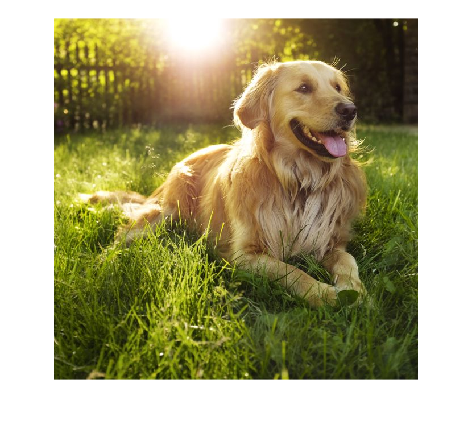

img = imread("img.jpg");
imshow(img);

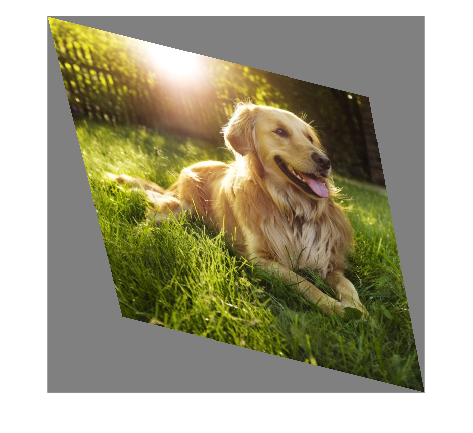


% T = [1              rand()-0.5    rand()/1000000;
%      rand()-0.5      1             rand()/10000;
%      rand()/100000   0             1];

T = [1              0.25    0;
    0.25      1             1/10000;
    1/100000   0             1];
t_proj = projective2d(T);   

I_projective = imwarp(img,t_proj,'FillValues',128);
imshow(I_projective)